
cd 'D:\Work\Code\Intracellular-recording-analysis\LUTs';
filepath = readlines('ampsweeplist.txt');
dataDirectory = extractBefore(filepath, '_');
filename = extractAfter(filepath, "_");
nfiles = length(filename);

cellID = replace(join([dataDirectory filename], " "),"_"," ");
cellID = extractBetween(cellID, "2022-"," T" | " blwgn");

for irow = 1:nfiles
P = getStructP(dataDirectory(irow), filename(irow),[nan nan],1);
fs = P.fs;

startPt = P(end).OFF_dur*P(end).fs+1;
stopPt = (P(end).OFF_dur + P(end).ON_dur)*P(end).fs;
resp = P(1).raster(:,startPt:stopPt);
stim = P(1).mean_movement(startPt:stopPt);
mean_pos = mean(stim(1,:));
time = linspace(0,P(end).ON_dur,P(end).ON_dur*fs);

% locs = [];
% zc = nan([1,length(stim)]);
% for j = 2:length(stim)
%     if (stim(1,j-1)<=mean_pos && stim(1,j)>=mean_pos && stim(1,j+1)>mean_pos)
%         zc(j) = 1;
%     end
% end
% locs = find(zc==1);

[pks,locs] = findpeaks(stim,"MinPeakDistance",fs/(2*P.amp_sweep_frq), "MinPeakHeight",0.01);

idx = 1;
while ~isempty(idx)
    idx = [];
    period_at_locs = 1./P.amp_sweep_frq;
    diff_locs = diff(locs)/fs;
    for i=1:length(diff_locs)
        if diff_locs(i)<period_at_locs/2
            idx = [idx;i];
        end
    end
    locs(idx+1)=[];
end


% figure;
% A1 =  subplot(2,1,1); 
figure;
plot(time, stim(1,:)); hold on; plot(locs/fs, stim(1, locs), 'rx'); yline(mean_pos); hold off;
[rr,cc] = find(resp); 
yyaxis right; plot(cc/fs,rr,'k|');

pause;

end

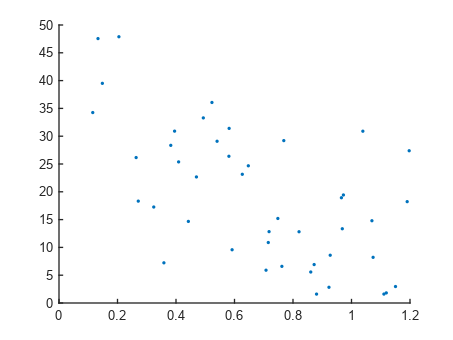


stim_clips = [];
resp_clips = [];
I_spike_phase = [];
amp_val = [];
spike_time_sd = [];

amp_val_list = [];
spike_time_list = [];

I = 1; 

% figure;

% figure;
% plot(time, stim(1,:)); hold on; plot(locs/fs, stim(1, locs), 'rx'); yline(mean_pos); hold off;
% yyaxis right; plot(cc/fs,rr,'k|');hold on;


for k= 2:length(locs)
    stim_clips = stim(1, locs(k-1):locs(k));
    resp_clips = resp(:, locs(k-1):locs(k));
    

    % yyaxis left; plot((locs(k-1):locs(k))./fs,stim_clips, 'k-');
    
    
    [row_ind,col_ind] = find(resp_clips == 1);
    % yyaxis right; plot((locs(k-1)+col_ind)./fs, row_ind, 'm|');
    % pause; 

    [C, ia, ic] = unique(row_ind, 'stable');
    ind = col_ind(ia);
    
    
  
    
    if length(col_ind)>=1
        I_spike_time = ind/fs;
        if length(ind) == P(1).complete_trials
            spike_time_sd(I) = (std(I_spike_time))*1000;
            %             I_spike(I) = freq(ind(1)+locs(k-1));%stim_freq(k-1);
            amp_val(I) = max(stim_clips) - min(stim_clips);
            mean_spike_time(I) = mean(I_spike_time)*1000;
            
            if amp_val(I) > 0.01
                amp_val_list = [amp_val_list amp_val(I).*ones(1,length(ind))];
                spike_time_list = [spike_time_list (ind.*1000/fs)'];
                
%                 scatter(amp_val(I).*ones(1,length(ind)), ((ind./fs)'));
%                 hold on;
            end
            
            I=I+1;
                        
        end
    end
    
    
   
end



figure;
scatter(amp_val, spike_time_sd, 6, "filled");

%{
stim_clips = [];
resp_clips = [];
I_spike_phase = [];
amp_val = [];
spike_time_sd = [];

amp_val_list = [];
spike_time_list = [];

I = 1; 

figure;

for k= 2:length(locs)
    stim_clips = stim(1, locs(k-1):locs(k));
    resp_clips = resp(:, locs(k-1):locs(k));
    
    [r,lags] = xcorr(stim_clips, sum(resp_clips,1), 'normalized');
    [M,I] = max(r);
    plot(lags(I), M, 'o'); hold on;
    
    [row_ind,col_ind] = find(resp_clips == 1);
    
    
    [C, ia, ic] = unique(row_ind, 'stable');
    ind = col_ind(ia);
    
    
    
    
%         figure;
%         plot(stim_clips); hold on; plot(ind, stim_clips(ind), 'rx');
    
    if length(col_ind)>=1
        %             I_spike_phase(I) = get_spike_phase(ind(1), fs, stim_period(ind(1)));
        %             I_spike_phase(I) = get_spike_phase(ind(1), fs, stim_period(k-1));
        I_spike_time = ind/fs;
        if length(ind) == P(1).complete_trials
            spike_time_sd(I) = (std(I_spike_time));
            %             I_spike(I) = freq(ind(1)+locs(k-1));%stim_freq(k-1);
            amp_val(I) = max(stim_clips) - min(stim_clips);
            mean_spike_time(I) = mean(I_spike_time);
            
            if amp_val(I) > 0.01
                amp_val_list = [amp_val_list amp_val(I).*ones(1,length(ind))];
                spike_time_list = [spike_time_list (ind./fs)'];
                
%                 scatter(amp_val(I).*ones(1,length(ind)), ((ind./fs)'));
%                 hold on;
            end
            
            I=I+1;
                        
        end
    end
    
    
    
    %     elseif stim_type == "amp"
    %
    %         stim_period = 1/freq;
    % %         stim_freq = 1 ./ (diff(locs) / fs);
    % %         stim_period = 1./stim_freq;
    %
    %         if length(ind)>=1
    %             I_spike_phase(I) = get_spike_phase(ind(1), fs, stim_period);
    %             I_spike(I) = max(stim_clips) - min(stim_clips);
    %             I=I+1;
    %         end
    %
    %
    %     end
end



figure;
[f, gof] = fit(amp_val_list', spike_time_list', 'poly1')
plot(f, amp_val_list, spike_time_list);

valid_amp_idx = find(amp_val > 0.01);
    
valid_amp = amp_val(valid_amp_idx);
valid_jitter_vals = (spike_time_sd(valid_amp_idx))*1000; %in ms
valid_mean_spike_time = mean_spike_time(valid_amp_idx);

figure;
% scatter(I_spike, spike_time_sd, 20, "filled")
% [f, gof] = fit(I_spike', spike_time_sd', 'poly1')
% plot(f, I_spike, spike_time_sd)

[f, gof] = fit(valid_amp', valid_jitter_vals', 'poly1')
plot(f, valid_amp, valid_jitter_vals);

ylabel('Jitter (ms)');
xlabel('Stimulus amplitude (mm)')
xlim([0 0.03])
ylim([0 11])
box off;
% title(LUT_intra_row_idx)

meta_ampsweep_jitter(struct_id).LUT_idx = LUT_intra_row_idx;
meta_ampsweep_jitter(struct_id).amp = amp_val_list;
meta_ampsweep_jitter(struct_id).spike_times = spike_time_list;
struct_id = struct_id + 1

%}
